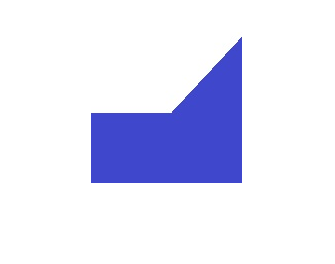

clear
close
clc

a=imread('C:\Users\Admin\Desktop\stain.jpg');
%imtool(a);

start_row=550-1;
start_col=150-1;

Cr_a=a(150:300,550:700,:);
imshow(Cr_a);

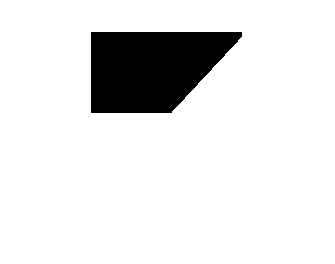

l=rgb2gray(Cr_a);
bw=imbinarize(l);
bw=~bw;
imshow(bw);

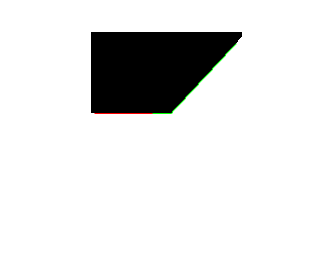


%dim=size(bw);

col1=4;
row1=find(bw(:,col1),1);

row2=12;
col2=find(bw(row2,:),1);

boundary1=bwtraceboundary(bw,[row1 col1],'N',8,90);

boundary2=bwtraceboundary(bw,[row2 col2],'E',8,90,'counter');

imshow(bw);
hold on;
plot(boundary1(:,2),boundary1(:,1),'r');
plot(boundary2(:,2),boundary2(:,1),'g');
hold off;


ab1=polyfit(boundary1(:,2),boundary1(:,1),1);
ab2=polyfit(boundary2(:,2),boundary2(:,1),1);

vect1=[1 ab1(1)];
vect2=[1 ab2(1)];
dp=dot(vect1,vect2);

length1=sqrt(sum(vect1.^2));
length2=sqrt(sum(vect2.^2));

angle=180-acos(dp/(length1*length2))*180/pi

angle = 139.7426

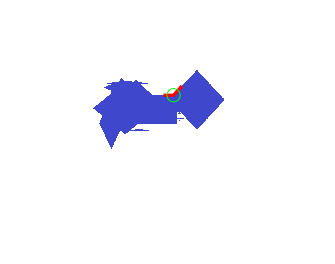



int=[1,-ab1(1);1,-ab2(1)]\[ab1(2);ab2(2)];
int=int+[start_col+1+1;start_row+1+3];          %WTF?????

imshow(a);
hold on;

plot(start_row+boundary1(:,2),start_col+boundary1(:,1),'r','LineWidth',2);
plot(start_row+boundary2(:,2),start_col+boundary2(:,1),'r','LineWidth',2);

int_x=int(2);
int_y=int(1);

plot(int_x,int_y,'g-o','MarkerSize',8);

hold off;